L_effs = []


L_effs =

     []



gyrodata = readtable('output_gyro1.txt')

gyrodata = 662×1 table
    Var1 
    _____

     -1.7
    -1.72
    -1.75
    -1.76
    -1.78
    -1.79
     -1.8
     1.66
     1.66
     1.66
     1.66
     1.67
     1.68
      1.7
     1.71
     1.73


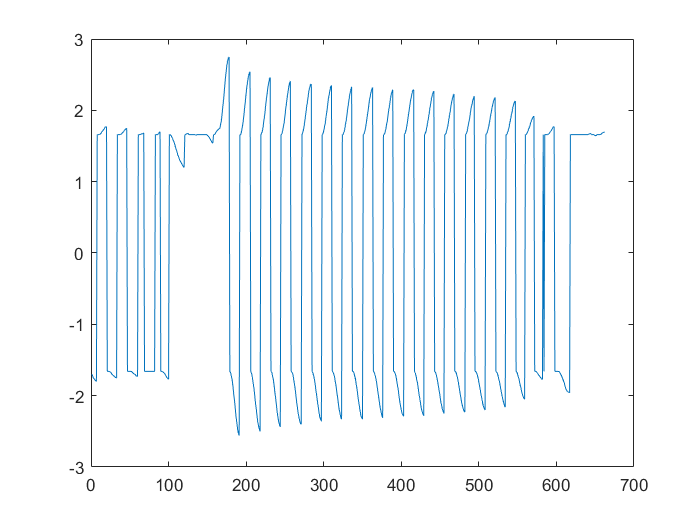

angles = gyrodata.Var1;
angles = angles;
t = 0:0.05:50;
plot(angles)

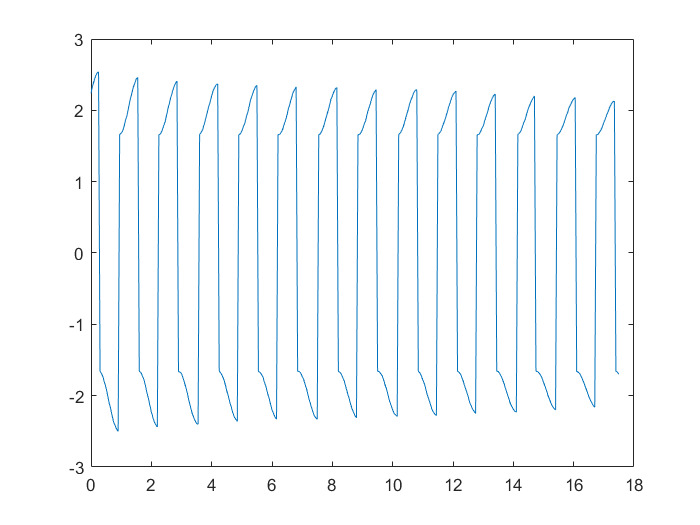


t = t(1:length(angles))';
angles = angles(200:550);
t = t(200:550) - t(200);
plot(t, angles)

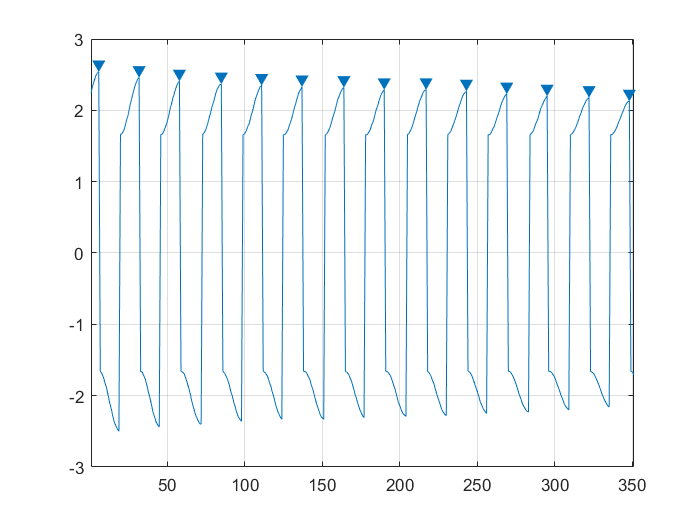

findpeaks(angles)

[pks, locs] = findpeaks(angles)

pks =     2.5400
    2.4600
    2.4100
    2.3700
    2.3500
    2.3300
    2.3200
    2.2900
    2.2900
    2.2700


locs =      6
    32
    58
    85
   111
   137
   164
   190
   217
   243


times_pks = t(locs)

times_pks =     0.2500
    1.5500
    2.8500
    4.2000
    5.5000
    6.8000
    8.1500
    9.4500
   10.8000
   12.1000


period_sd = std(diff(times_pks))

period_sd = 0.0240

period = mean(diff(times_pks))

period = 1.3154

wn = 2*pi/period

wn = 4.7767


l_eff = 9.81/wn^2

l_eff = 0.4299

L_effs = [L_effs; l_eff]

L_effs = 0.4299

gyrodata = readtable('output_gyro.txt')

gyrodata = 747×1 table
    Var1
    ____

    1.73
    1.74
    1.75
    1.77
    1.78
    1.79
     1.8
    1.81
    1.82
    1.83
    1.84
    1.84
    1.85
    1.86
    1.86
    1.87


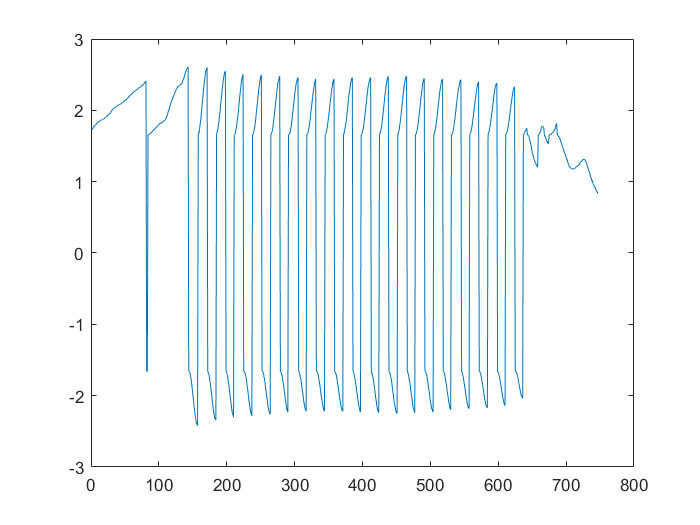

angles = gyrodata.Var1;
angles = angles;
t = 0:0.05:50;
plot(angles)

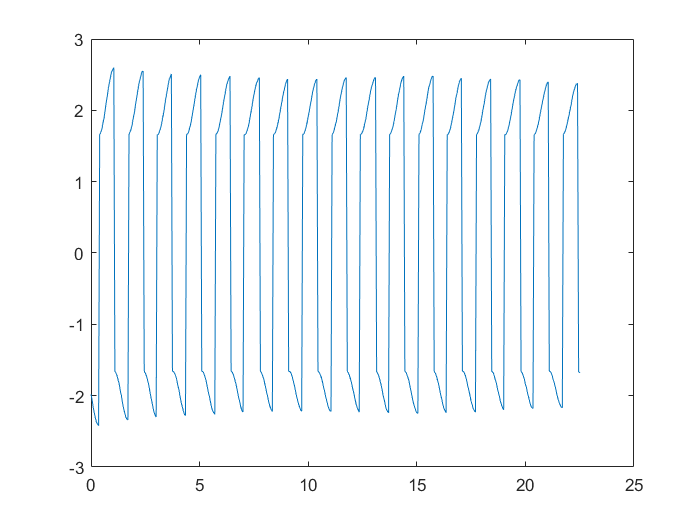


t = t(1:length(angles))';
angles = angles(150:600);
t = t(150:600) - t(150);
plot(t, angles)

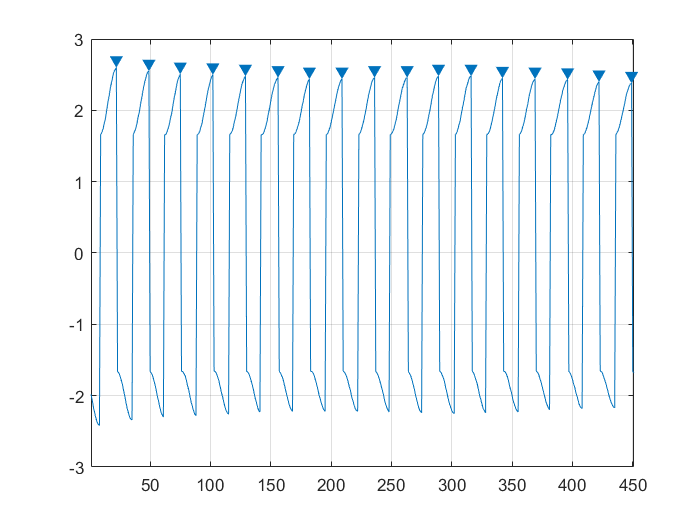

findpeaks(angles)

[pks, locs] = findpeaks(angles)

pks =     2.6000
    2.5500
    2.5100
    2.5000
    2.4800
    2.4600
    2.4400
    2.4400
    2.4600
    2.4600


locs =     22
    49
    75
   102
   129
   156
   182
   209
   236
   263


times_pks = t(locs)

times_pks =     1.0500
    2.4000
    3.7000
    5.0500
    6.4000
    7.7500
    9.0500
   10.4000
   11.7500
   13.1000


period_sd = std(diff(times_pks))

period_sd = 0.0239

period = mean(diff(times_pks))

period = 1.3344

wn = 2*pi/period

wn = 4.7087


l_eff = 9.81/wn^2

l_eff = 0.4425

L_effs = [L_effs; l_eff]

L_effs =     0.4299
    0.4425


l_eff = mean(L_effs)

l_eff = 0.4362